clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';




PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./6;
phi = pi./2 - phi;
shenglunum = 5;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.2;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,0.2);

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


PointTable_A_off8 =     0.3370    0.5073    0.5611    0.5094    0.3390   -0.1407   -0.3096   -0.3609   -0.3067   -0.1362
   -0.5714   -0.4665   -0.2681   -0.0433    0.1469    0.2584    0.1531   -0.0459   -0.2714   -0.4616
    0.4309    0.5900    0.7359    0.8361    0.8477    0.6551    0.4966    0.3518    0.2527    0.2411


PointTable_B_off8 =     0.3370    0.5073    0.5611    0.5094    0.3390   -0.1407   -0.3096   -0.3609   -0.3067   -0.1362
   -0.4615   -0.2713   -0.0459    0.1530    0.2579    0.1465   -0.0434   -0.2681   -0.4664   -0.5713
    0.2409    0.2526    0.3518    0.4968    0.6559    0.8486    0.8363    0.7359    0.5899    0.4307


XieMianPianYi =     0.0150    0.0150         0    0.0150    0.0150    0.0149    0.0149         0    0.0150    0.0150


## 验证

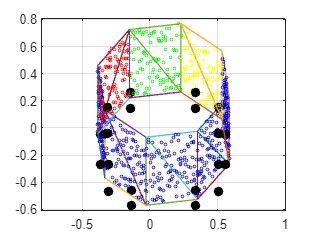

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

## 构建复测数据

% 构建测点输入
PointIn = [];
for i = 1:shenglunum
    temp = [PointTable_A_off8(:,i),PointTable_A_off8(:,end+1-i)];
    PointIn = [PointIn,temp];
end

% 计算参数（用于输入）
[PlaneParaOut,TrianglePoints4,~,~] = planefit4(side_faces_transformed1',side_faces_transformed3',side_faces_transformed5',side_faces_transformed7',P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,~,Tao,~] = Calculate_rectangle_from_vertex(TrianglePoints4);




## 计算距离

LenDaoJiao = 0.2*ones(1,8);
[Distance,theta,LTPY,TiC,Wquanzhong3,Wquanzhong4]=JuXingFuCe(PointIn,shenglunum,Pin,Tao,h,PlaneParaOut,LenDaoJiao)

Distance =     0.5216    0.9025    1.0232    0.9081    0.5288


theta =     2.0047    2.0173    2.0193    2.0174    2.0051


LTPY =    -1.1511   -0.7801   -0.6609   -0.7746   -1.1442


TiC =    -0.8956   -0.5279    0.0000    0.5279    0.8956


Wquanzhong3 =     0.2552
    0.2552
    0.4618
    0.4618
    0.5661
    0.5661
    0.4618
    0.4618
    0.2551
    0.2551


Wquanzhong4 =     0.2430
    0.2430
    0.4731
    0.4731
    0.5562
    0.5562
    0.4731
    0.4731
    0.2430
    0.2430
